load carsmall

X = [Weight, Horsepower, Acceleration];

lm = fitlm(X, MPG)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                         Estimate                  SE                    tStat                  pValue       
                   ____________________    ___________________    ___________________    ____________________

    (Intercept)        47.9767628118615       3.87851641748551        12.369874881944    4.89570341689011e-21
    x1             -0.00654155878851795    0.00112741016370336      -5.80228828790225    9.87424814144022e-08
    x2              -0.0429433065881864     0.0243130608813806      -1.76626492228599      0.0807803098213113
    x3              -0.0115826516894869      0.193325043113178    -0.0599128364487476       0.952359384151779


Number of observations: 93, Error degrees of freedom:


% Resursa:
% mathworks.com/help/stats/understanding-linear-regression-outputs.html
% https://www.mathworks.com/help/matlab/data_analysis/linear-regression.html#:~:text=In%20MATLAB%2C%20you%20can%20find,a%20state%20using%20the%20%5C%20operator.


anova(lm, 'summary')

ans = 3×5 table
                     SumSq          DF         MeanSq                F                   pValue       
                ________________    __    ________________    ________________    ____________________

    Total       6004.75806451613    92    65.2691093969145                                            
    Model       4515.95635987069     3    1505.31878662356    89.9873848823964    7.38158416319924e-27
    Residual    1488.80170464544    89      16.72810904096                                            



% Coefficient confidance intervals

coeficient=coefCI(lm) % Display coefficient intervals

coeficient =   40.270233304632377  55.683292319090633
  -0.008781698769403  -0.004301418807632
  -0.091252840679289   0.005366227502916
  -0.395715394436506   0.372550091057532


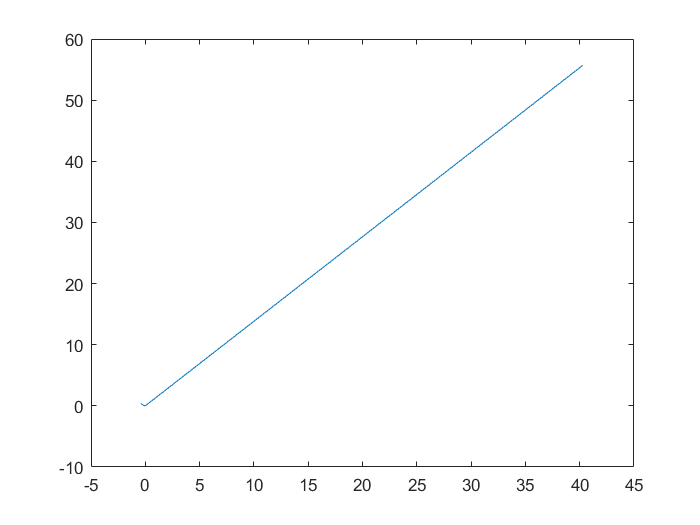


coeficient22=coeficient2;
coeficient33=coeficient3;

plot(coeficient22, coeficient33)


coefCI(lm, 0.01) % you can also change the confidacne level. Find the 99% confidance intervals for the coefficients

ans =   37.767715642118084  58.185809981604926
  -0.009509132546619  -0.003573985030416
  -0.106940247341058   0.021053634164685
  -0.520453640435917   0.497288337056943
